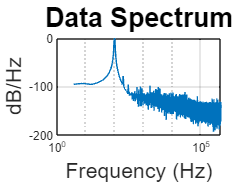

@Freq = 100.000, SNR = 85.501 dB, SNDR = 76.579 dB, SFDR = 77.540 dB, HD2 = 77.540 and HD3 = 96.823


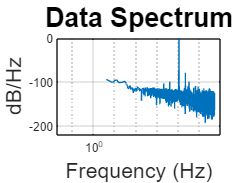

@Freq = 10411.825, SNR = 83.962 dB, SNDR = 49.976 dB, SFDR = 79.748 dB, HD2 = 79.748 and HD3 = 99.685


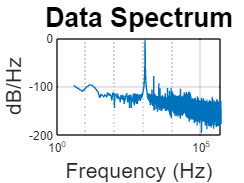

@Freq = 1153.072, SNR = 87.027 dB, SNDR = 68.374 dB, SFDR = 78.085 dB, HD2 = 78.085 and HD3 = 93.314


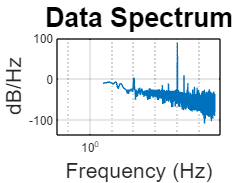

@Freq = 100.000, SNR = 81.274 dB, SNDR = -88.748 dB, SFDR = 13.592 dB, HD2 = 13.592 and HD3 = 24.349


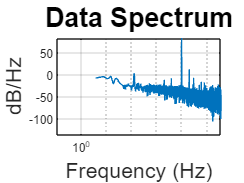

@Freq = 127.231, SNR = 82.166 dB, SNDR = -92.018 dB, SFDR = 21.668 dB, HD2 = 21.668 and HD3 = 26.757


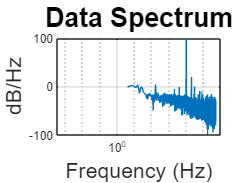

@Freq = 161.877, SNR = 82.904 dB, SNDR = -98.385 dB, SFDR = 18.277 dB, HD2 = 18.277 and HD3 = 23.902


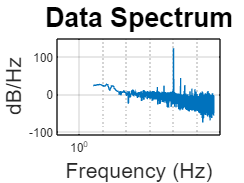

@Freq = 205.957, SNR = 83.200 dB, SNDR = -123.134 dB, SFDR = -3.230 dB, HD2 = -0.535 and HD3 = -3.230


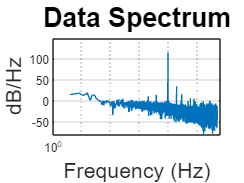

@Freq = 262.041, SNR = 83.190 dB, SNDR = -114.376 dB, SFDR = 7.344 dB, HD2 = 7.344 and HD3 = 8.503


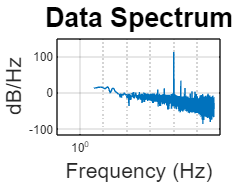

@Freq = 333.397, SNR = 83.191 dB, SNDR = -111.236 dB, SFDR = 5.658 dB, HD2 = 8.895 and HD3 = 5.658


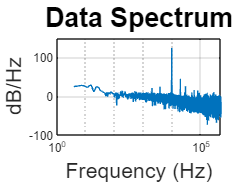

@Freq = 424.183, SNR = 83.200 dB, SNDR = -124.774 dB, SFDR = -7.121 dB, HD2 = -3.849 and HD3 = -7.121


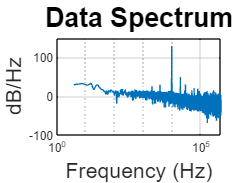

@Freq = 539.692, SNR = 83.200 dB, SNDR = -128.419 dB, SFDR = -6.560 dB, HD2 = -6.560 and HD3 = -5.825


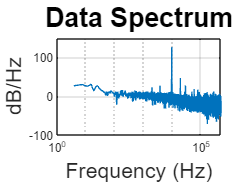

@Freq = 686.654, SNR = 83.200 dB, SNDR = -126.985 dB, SFDR = -1.428 dB, HD2 = -1.428 and HD3 = 0.717


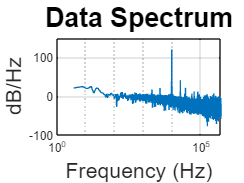

@Freq = 873.636, SNR = 83.200 dB, SNDR = -121.438 dB, SFDR = 5.308 dB, HD2 = 5.308 and HD3 = 6.553


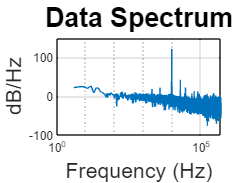

@Freq = 1111.534, SNR = 83.200 dB, SNDR = -121.464 dB, SFDR = 0.349 dB, HD2 = 0.349 and HD3 = 7.135


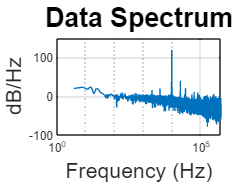

@Freq = 1414.214, SNR = 83.200 dB, SNDR = -119.600 dB, SFDR = 1.346 dB, HD2 = 4.029 and HD3 = 1.346


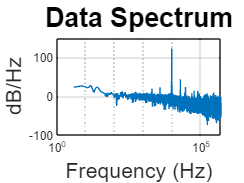

@Freq = 1799.315, SNR = 83.200 dB, SNDR = -122.957 dB, SFDR = 2.145 dB, HD2 = 2.145 and HD3 = 18.019


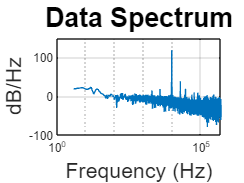

@Freq = 2289.283, SNR = 83.200 dB, SNDR = -118.840 dB, SFDR = 2.324 dB, HD2 = 2.324 and HD3 = 8.812


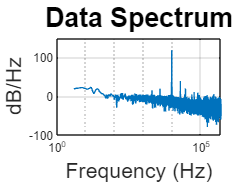

@Freq = 2912.674, SNR = 83.200 dB, SNDR = -118.235 dB, SFDR = 2.719 dB, HD2 = 11.788 and HD3 = 2.719


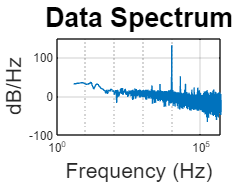

@Freq = 3705.818, SNR = 83.200 dB, SNDR = -130.636 dB, SFDR = -4.619 dB, HD2 = -4.619 and HD3 = 3.255


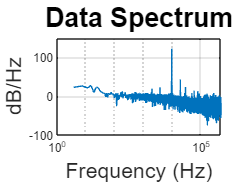

@Freq = 4714.942, SNR = 83.200 dB, SNDR = -123.250 dB, SFDR = -0.576 dB, HD2 = -0.576 and HD3 = 23.862


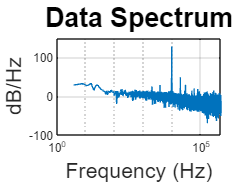

@Freq = 5998.859, SNR = 83.200 dB, SNDR = -128.016 dB, SFDR = -1.821 dB, HD2 = -1.821 and HD3 = -0.672


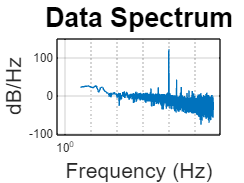

@Freq = 7632.396, SNR = 83.200 dB, SNDR = -121.226 dB, SFDR = 5.490 dB, HD2 = 5.490 and HD3 = 13.035


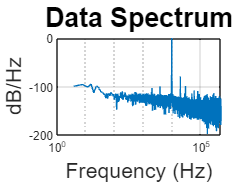

@Freq = 9710.759, SNR = 84.775 dB, SNDR = 50.487 dB, SFDR = 79.794 dB, HD2 = 79.794 and HD3 = 99.474


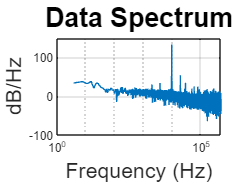

@Freq = 12355.077, SNR = 83.200 dB, SNDR = -134.140 dB, SFDR = 9.636 dB, HD2 = 9.636 and HD3 = 13.395


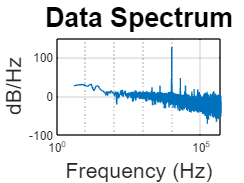

@Freq = 15719.464, SNR = 83.200 dB, SNDR = -127.026 dB, SFDR = 1.506 dB, HD2 = 1.506 and HD3 = 6.930


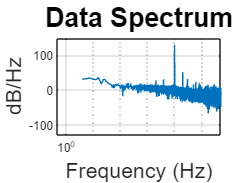

@Freq = 20000.000, SNR = 83.200 dB, SNDR = -131.032 dB, SFDR = -2.241 dB, HD2 = -2.241 and HD3 = 5.129


clearvars

## Find the SNR SNDR

clearvars
folderPath = 'C:\Chengming_Li\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data';  % Specify the folder path
pattern = 'output-freq-*.bin';    % Define the file name pattern
% Get a list of files matching the pattern
files = dir(fullfile(folderPath, pattern));
files_name = strings(length(files), 1);
frequencies1 = zeros(1,length(files));
for i = 1:length(files)
    temp = files(i).name;
    files_name(i) = convertCharsToStrings(temp);
end
for k = 1:length(files)
    % Get the full path of the file
    filePath = fullfile(folderPath, files(k).name);
    
    % Extract frequency from the file name
    matches = regexp(files(k).name, 'output-freq-([\d.]+)', 'tokens');
    if ~isempty(matches)
        frequency = string(matches);
        frequency = regexprep(frequency, '(?<=\d+\.\d*)\.', '');
        frequencies1(1,k) = str2double(frequency);
        
    else
        disp('Frequency not found.');
    end
end
Data_filt = zeros(262144,length(frequencies1));
for i = 1:length(frequencies1)
    file_path = strcat("C:\Chengming_Li\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data\", files_name(i,1));
    fileID = fopen(file_path);
    bin_data = fread(fileID,'uint16');
    
    % Remove the zeros
    filtered_data = bin_data(bin_data ~= 0);
    filtered_data =filtered_data';
    Data_filt(:,i) = bin_data(1:4:end);
end
Set = zeros(3,length(frequencies1));
Fs=1e6;
num_segments=1;
f_s = Fs;
BW =500e3;
sample_size=2^18;
periodogram_length = sample_size / num_segments;
fbin = f_s / periodogram_length;
plotYN = 0; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
for i = 1: length(frequencies1)
    f_signal = frequencies1(1,i);
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
    plot_periodogram_SFDR(Data_filt(:,i), periodogram_length, num_segments, f_signal, ...
    f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    %fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    Set(1,i) = f_signal;
    Set(2,i) = SNR;
    Set(3,i) = SNDR;
end
% Sort the array
[~, idx] = sort(Set(1, :)); 
Set = Set(:, idx); 
save('Set.mat', 'Set');

## Plot SNR And SNDR from 0.1k to 250kHz

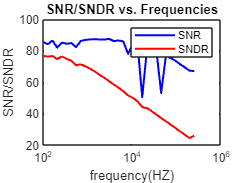

load('Set.mat')
figure
semilogx(Set(1,:), Set(2,:), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(Set(1,:), Set(3,:), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR");
title("SNR/SNDR vs. Frequencies");
legend;

## Find SFDR

clearvars
folderPath = 'C:\Chengming_Li\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data2';  % Specify the folder path
pattern = 'output-freq-*.bin';    % Define the file name pattern
% Get a list of files matching the pattern
files = dir(fullfile(folderPath, pattern));
files_name = strings(length(files), 1);
frequencies2 = zeros(1,length(files));
for i = 1:length(files)
    temp = files(i).name;
    files_name(i) = convertCharsToStrings(temp);
end
for k = 1:length(files)
    % Get the full path of the file
    filePath = fullfile(folderPath, files(k).name);
    % Extract frequency from the file name
    matches = regexp(files(k).name, 'output-freq-([\d.]+)', 'tokens');
    if ~isempty(matches)
        frequency = string(matches);
        frequency = regexprep(frequency, '(?<=\d+\.\d*)\.', '');
        frequencies2(1,k) = str2double(frequency);
    else
        disp('Frequency not found.');
    end
end
Data_filt = zeros(262144,length(frequencies2));
for i = 1:length(frequencies2)
    file_path = strcat("C:\Chengming_Li\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data2\", files_name(i,1));
    fileID = fopen(file_path);
    bin_data = fread(fileID,'uint16');
    freq = frequencies2(1,i);
    
    % Remove the zeros
    filtered_data = bin_data(bin_data ~= 0);
    filtered_data =filtered_data';
    Data_filt(:,i) = bin_data(1:4:end);
end
Set2 = zeros(2,length(frequencies2));
Fs=1e6;
num_segments=1;
f_s = Fs;
BW =500e3;
sample_size=2^18;
periodogram_length = sample_size / num_segments;
fbin = f_s / periodogram_length;
plotYN = 0; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
for i = 1: length(frequencies2)
    f_signal = frequencies2(1,i);
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
    plot_periodogram_SFDR(Data_filt(:,i), periodogram_length, num_segments, f_signal, ...
    f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    % fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    Set2(1,i) = f_signal;
    Set2(2,i) = SFDR;
end
% Sort the array
[~, idx] = sort(Set2(1, :)); 
Set2 = Set2(:, idx); 
save('Set2.mat', 'Set2');


## Plot SFDR from 0.1k to 20kHz

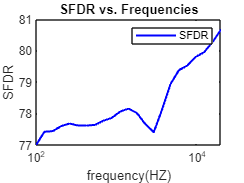

load('Set2.mat')
figure
semilogx(Set2(1,:), Set2(2,:), 'b-', 'LineWidth', 1.5,"DisplayName","SFDR");

xlabel("frequency(HZ)"); ylabel("SFDR");
title("SFDR vs. Frequencies");
legend;